**Simulation of robotic systems**

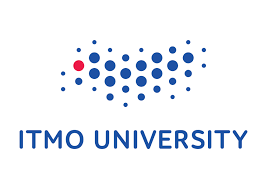

**Name: Klinsmann Agyei**

**ISU Number: 373260**

**Lab 4**

Simulation and control of a spatial PPR robot. Here we use a dynamic model of a robot to calculate the control law without using a PID controller. 

clear; clc; 
% to clear the workspace and command window 

#### Parameters / Параметры

m1 = 16.726;
m2 = 6.237;
m3 = 12.243;
l1 = 0.23;
l2 = 0.43;
l3 = 0.19;
w1 = 0.069;
w2 = 0.129;
w3 = 0.057;
kp = 700; ki = 100; kd = 250; % PID controller coeffitients 
StopTime = 20;
AB = [l1 w1 w1]; % m dimensions of the first link
BC = [w2 w2 l2];
CD = [w3 w3 l3]; 

b = 0.0; % friction coefficient 

StopTime = 20; % simulation time

% Data for the Repeating Sequence blocks 

#### Run the section to run the model

addpath(genpath('mr')); % we use function library by Kevin Lynch 

Lab4_PPR_Dynamics % it opens the model 
simOut = sim('Lab4_PPR_Dynamics'); % it runs it 


#### Model description

The robot's structure and parameters are the same as in the previous example. Look there to find comments on the inverse kinematics problem.  Here, we do not use a PID controller but a feedback linearization trick to control the robot. Proceed by the links to find out more about 

The aim is to derive the robot's manipulator dynamics equation in the form of 

$M(q)\ddot{q} + C(q, \dot{q}) + N(q) = u$,

then to choose the following control law 

$u  = M(q)[M(q)^{-1}(C(q,\dot{q}) + N(q)) + u']$,

and to come up with the following torque equation 

$\tau = M(q)u' + C(q, \dot{q}) + N(q)$,

where $u' $ is the additional control effort

$u' = \ddot{q}_d + K_v(\dot{q}_d -\dot{q}_a)+ K_p (q_d-q_a)$,

where $\ddot{q}_d$ is the desired acceleration, $\dot{q}_d, \dot{q}_a$ are the desired and actual angular velocities, $q_d, q_a$ are the desired and actual positions, $K_v,  K_p $ are coefficients 

Look the file [./Lab4_dynamics_livescript.mlx](matlab:open('./Dynamics.mlx')) to derive the dynamics equation.

#### Plots

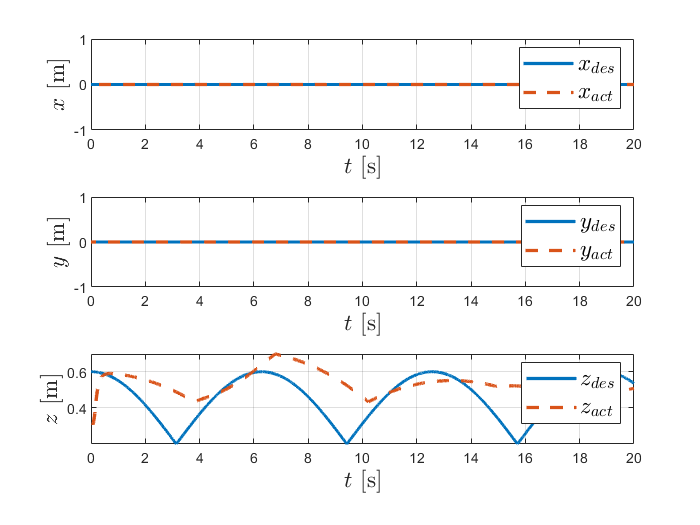

figure;
subplot(3,1,1);
plot(outputs.p_des.time, outputs.p_des.data(:,1),...
     outputs.p_act.time, outputs.p_act.data(:,1),'--', 'linewidth', 2);
grid on;
legend('$x_{des}$', '$x_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$x$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
subplot(3,1,2);
plot(outputs.p_des.time, outputs.p_des.data(:,2),...
     outputs.p_act.time, outputs.p_act.data(:,2),'--', 'linewidth', 2);
grid on;
legend('$y_{des}$', '$y_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$y$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
subplot(3,1,3);
plot(outputs.p_des.time, outputs.p_des.data(:,3),...
     outputs.p_act.time, outputs.p_act.data(:,3),'--', 'linewidth', 2);
grid on;
legend('$z_{des}$', '$z_{act}$',  'fontsize',14,'interpreter','latex');
ylabel('$z$ [m]', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');

**Plot of Torques and forces**

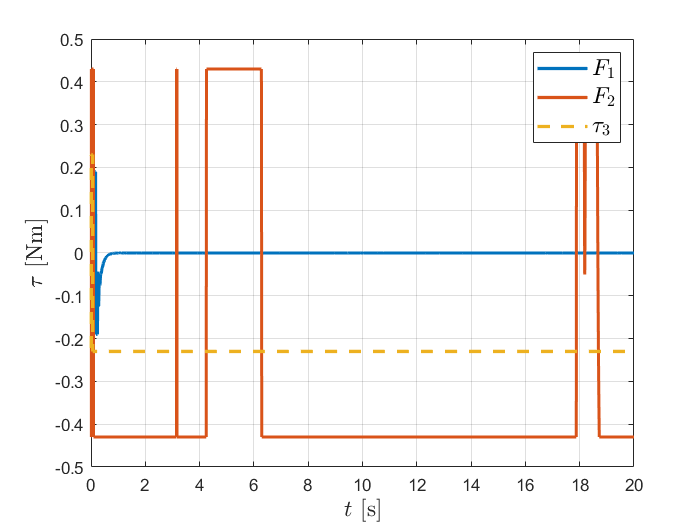


figure;
title('Joints torques');
plot(outputs.tau.time, outputs.tau.data(:,1),...
	 outputs.tau.time, outputs.tau.data(:,2),...
     outputs.tau.time, outputs.tau.data(:,3),'--', 'linewidth', 2);
grid on;
legend('$F_1$', '$F_2$', '$\tau_3$', 'fontsize',14,'interpreter','latex');
xlabel('$t$ [s]', 'fontsize',14,'interpreter','latex');
ylabel('$\tau$ [Nm]', 'fontsize',14,'interpreter','latex');